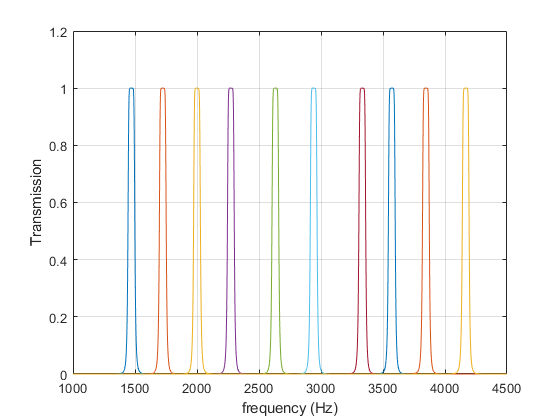

clear;

players = [1471, 1724, 2000, 2273, 2632, 2941, 3333, 3571, 3846, 4167];
% Player center frequencies in Hz
fs = 10000; % sampling frequency (remember we have decimated)
Wc = 2*pi*0.01;
BW = 50; % Full bandwidth of filters in Hz
flower = players - BW/2; % Lower corner frequency of BPF
fupper = players + BW/2; % Upper corner frequency of BPF


N = 2048;
FF = -0.5:1/N:0.5-1/N;

[b1, a1] = butter(5, [flower(1)*2/fs, fupper(1)*2/fs]);
% IMPORTANT: ‘butter’ takes frequency specifications in half cycles/sample,
% not Hz, hence the division by f s and multiplication by 2
faxis = linspace(1000, 4500, 2000); % create a freq axis for plotting from 0 to 5 KHz
H1 = freqz(b1, a1, faxis, fs); % calculates the freq response H
% at the frequencies in f axis


figure(1);
plot(faxis, abs(H1)); % frequency response
grid on;
xlabel('frequency (Hz)');
ylabel('Transmission');
hold on;

[b2, a2] = butter(5, [flower(2)*2/fs, fupper(2)*2/fs]);

H2 = freqz(b2, a2, faxis, fs);

plot(faxis, abs(H2));


[b3, a3] = butter(5, [flower(3)*2/fs, fupper(3)*2/fs]);

H3 = freqz(b3, a3, faxis, fs);

plot(faxis, abs(H3));



[b4, a4] = butter(5, [flower(4)*2/fs, fupper(4)*2/fs]);

H4 = freqz(b4, a4, faxis, fs);

plot(faxis, abs(H4));




[b5, a5] = butter(5, [flower(5)*2/fs, fupper(5)*2/fs]);

H5 = freqz(b5, a5, faxis, fs);

plot(faxis, abs(H5));


[b6, a6] = butter(5, [flower(6)*2/fs, fupper(6)*2/fs]);

H6 = freqz(b6, a6, faxis, fs);

plot(faxis, abs(H6));


[b7, a7] = butter(5, [flower(7)*2/fs, fupper(7)*2/fs]);

H7 = freqz(b7, a7, faxis, fs);

plot(faxis, abs(H7));


[b8, a8] = butter(5, [flower(8)*2/fs, fupper(8)*2/fs]);

H8 = freqz(b8, a8, faxis, fs);

plot(faxis, abs(H8));



[b9, a9] = butter(5, [flower(9)*2/fs, fupper(9)*2/fs]);

H9 = freqz(b9, a9, faxis, fs);

plot(faxis, abs(H9));



[b10, a10] = butter(5, [flower(10)*2/fs, fupper(10)*2/fs]);

H10 = freqz(b10, a10, faxis, fs);

plot(faxis, abs(H10));

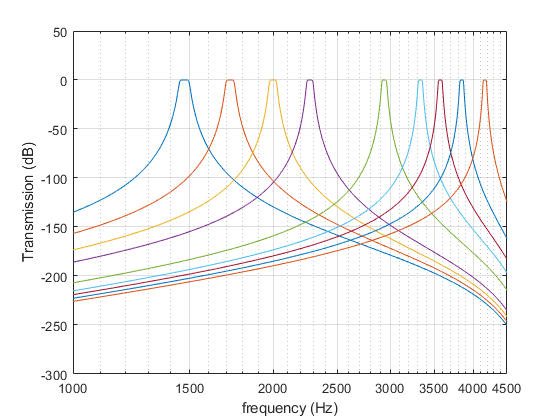





figure(2);


semilogx(faxis, 20*log10(abs(H1)));

hold on;
grid on;
xlabel('frequency (Hz)');
ylabel('Transmission (dB)');

semilogx(faxis, 20*log10(abs(H2)));

semilogx(faxis, 20*log10(abs(H3)));

semilogx(faxis, 20*log10(abs(H4)));

semilogx(faxis, 20*log10(abs(H6)));

semilogx(faxis, 20*log10(abs(H7)));

semilogx(faxis, 20*log10(abs(H8)));

semilogx(faxis, 20*log10(abs(H9)));

semilogx(faxis, 20*log10(abs(H10)));

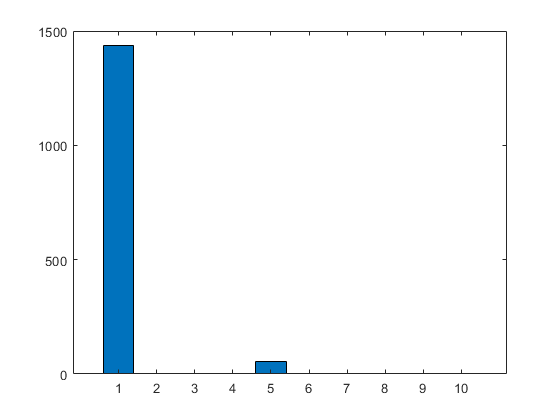




%Testing sample waves


t = linspace(0, 0.2, 2000);  % The time vector with a length of 0.2 seconds and 2000 total samples

x1 = square(2*pi*players(1)*t);     % Create the time domain square wave





F11 = filter(b1, a1, x1);
F12 = filter(b2, a2, x1);
F13 = filter(b3, a3, x1);
F14 = filter(b4, a4, x1);
F15 = filter(b5, a5, x1);
F16 = filter(b6, a6, x1);
F17 = filter(b7, a7, x1);
F18 = filter(b8, a8, x1);
F19 = filter(b9, a9, x1);
F110 = filter(b10, a10, x1);

Fe1 = 1:10;

Fe1(1) = sum(F11 .^ 2);
Fe1(2) = sum(F12 .* F12);
Fe1(3) = sum(F13 .* F13);
Fe1(4) = sum(F14 .* F14);
Fe1(5) = sum(F15 .* F15);
Fe1(6) = sum(F16 .* F16);
Fe1(7) = sum(F17 .* F17);
Fe1(8) = sum(F18 .* F18);
Fe1(9) = sum(F19 .* F19);
Fe1(10) = sum(F110 .* F110);

figure(3);

bar(Fe1);

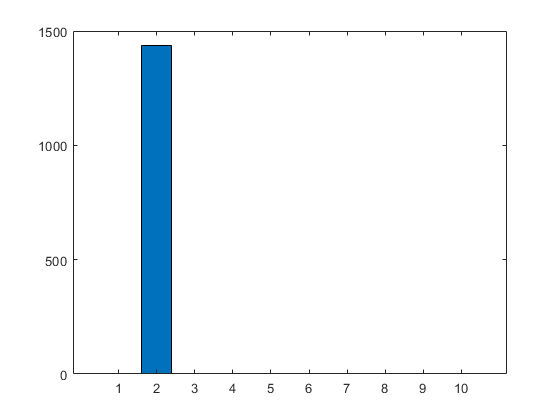



x2 = square(2*pi*players(2)*t);

%Player 2 filter


F21 = filter(b1, a1, x2);
F22 = filter(b2, a2, x2);
F23 = filter(b3, a3, x2);
F24 = filter(b4, a4, x2);
F25 = filter(b5, a5, x2);
F26 = filter(b6, a6, x2);
F27 = filter(b7, a7, x2);
F28 = filter(b8, a8, x2);
F29 = filter(b9, a9, x2);
F210 = filter(b10, a10, x2);

Fe2 = 1:10;

Fe2(1) = sum(F21 .* F21);
Fe2(2) = sum(F22 .* F22);
Fe2(3) = sum(F23 .* F23);
Fe2(4) = sum(F24 .* F24);
Fe2(5) = sum(F25 .* F25);
Fe2(6) = sum(F26 .* F26);
Fe2(7) = sum(F27 .* F27);
Fe2(8) = sum(F28 .* F28);
Fe2(9) = sum(F29 .* F29);
Fe2(10) = sum(F210 .* F210);

figure(4);

bar(Fe2);

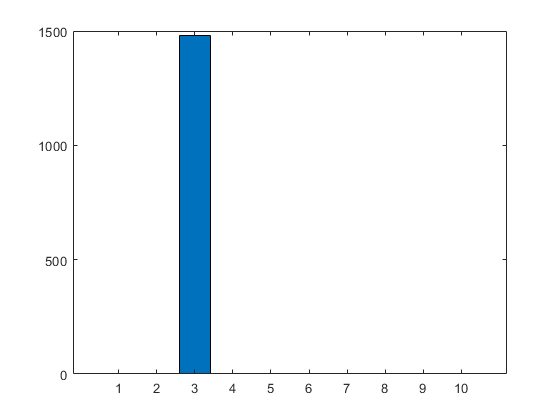


%player 3 filter

x3 = square(2*pi*players(3)*t);


F31 = filter(b1, a1, x3);
F32 = filter(b2, a2, x3);
F33 = filter(b3, a3, x3);
F34 = filter(b4, a4, x3);
F35 = filter(b5, a5, x3);
F36 = filter(b6, a6, x3);
F37 = filter(b7, a7, x3);
F38 = filter(b8, a8, x3);
F39 = filter(b9, a9, x3);
F310 = filter(b10, a10, x3);

Fe3 = 1:10;

Fe3(1) = sum(F31 .^2);
Fe3(2) = sum(F32 .^2);
Fe3(3) = sum(F33 .^2);
Fe3(4) = sum(F34 .^2);
Fe3(5) = sum(F35 .^2);
Fe3(6) = sum(F36 .^2);
Fe3(7) = sum(F37 .^2);
Fe3(8) = sum(F38 .^2);
Fe3(9) = sum(F39 .^2);
Fe3(10) = sum(F310 .^2);

figure(5);

bar(Fe3);

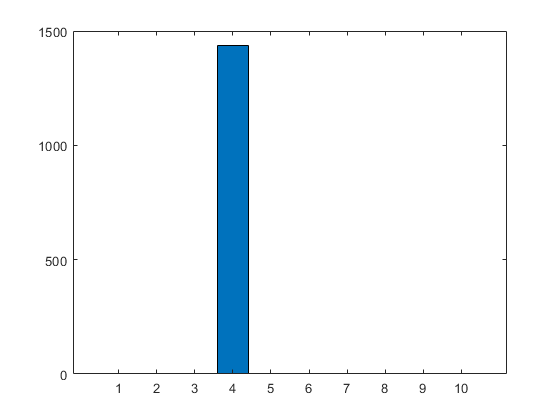




%player 4 filter

x4 = square(2*pi*players(4)*t);


F41 = filter(b1, a1, x4);
F42 = filter(b2, a2, x4);
F43 = filter(b3, a3, x4);
F44 = filter(b4, a4, x4);
F45 = filter(b5, a5, x4);
F46 = filter(b6, a6, x4);
F47 = filter(b7, a7, x4);
F48 = filter(b8, a8, x4);
F49 = filter(b9, a9, x4);
F410 = filter(b10, a10, x4);

Fe4 = 1:10;

Fe4(1) = sum(F41 .^2);
Fe4(2) = sum(F42 .^2);
Fe4(3) = sum(F43 .^2);
Fe4(4) = sum(F44 .^2);
Fe4(5) = sum(F45 .^2);
Fe4(6) = sum(F46 .^2);
Fe4(7) = sum(F47 .^2);
Fe4(8) = sum(F48 .^2);
Fe4(9) = sum(F49 .^2);
Fe4(10) = sum(F410 .^2);

figure(6);

bar(Fe4);

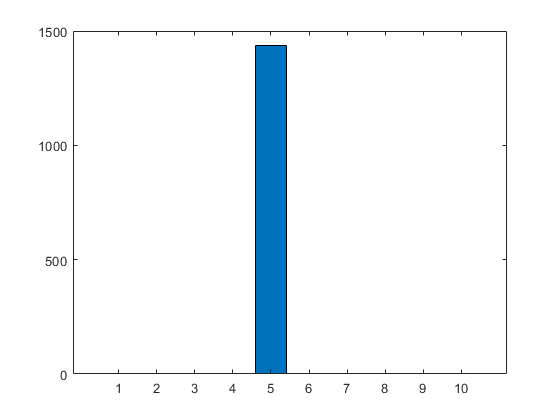



%player 5 filter

x5 = square(2*pi*players(5)*t);


F51 = filter(b1, a1, x5);
F52 = filter(b2, a2, x5);
F53 = filter(b3, a3, x5);
F54 = filter(b4, a4, x5);
F55 = filter(b5, a5, x5);
F56 = filter(b6, a6, x5);
F57 = filter(b7, a7, x5);
F58 = filter(b8, a8, x5);
F59 = filter(b9, a9, x5);
F510 = filter(b10, a10, x5);

Fe5 = 1:10;

Fe5(1) = sum(F51 .^2);
Fe5(2) = sum(F52 .^2);
Fe5(3) = sum(F53 .^2);
Fe5(4) = sum(F54 .^2);
Fe5(5) = sum(F55 .^2);
Fe5(6) = sum(F56 .^2);
Fe5(7) = sum(F57 .^2);
Fe5(8) = sum(F58 .^2);
Fe5(9) = sum(F59 .^2);
Fe5(10) = sum(F510 .^2);

figure(7);

bar(Fe5);

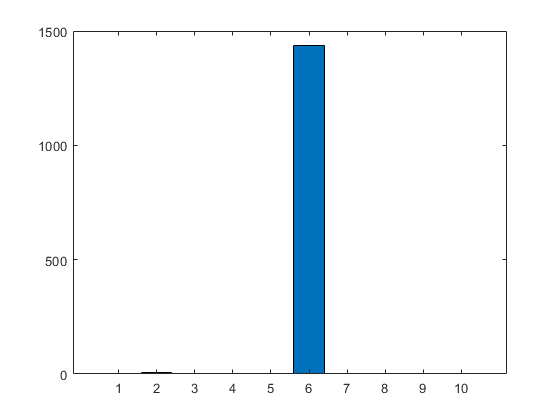




%player 6 filter

x6 = square(2*pi*players(6)*t);


F61 = filter(b1, a1, x6);
F62 = filter(b2, a2, x6);
F63 = filter(b3, a3, x6);
F64 = filter(b4, a4, x6);
F65 = filter(b5, a5, x6);
F66 = filter(b6, a6, x6);
F67 = filter(b7, a7, x6);
F68 = filter(b8, a8, x6);
F69 = filter(b9, a9, x6);
F610 = filter(b10, a10, x6);

Fe6 = 1:10;

Fe6(1) = sum(F61 .^2);
Fe6(2) = sum(F62 .^2);
Fe6(3) = sum(F63 .^2);
Fe6(4) = sum(F64 .^2);
Fe6(5) = sum(F65 .^2);
Fe6(6) = sum(F66 .^2);
Fe6(7) = sum(F67 .^2);
Fe6(8) = sum(F68 .^2);
Fe6(9) = sum(F69 .^2);
Fe6(10) = sum(F610 .^2);

figure(8);

bar(Fe6);

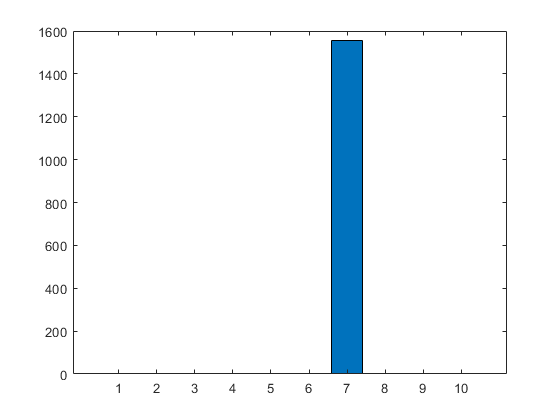




%player 7 filter

x7 = square(2*pi*players(7)*t);


F71 = filter(b1, a1, x7);
F72 = filter(b2, a2, x7);
F73 = filter(b3, a3, x7);
F74 = filter(b4, a4, x7);
F75 = filter(b5, a5, x7);
F76 = filter(b6, a6, x7);
F77 = filter(b7, a7, x7);
F78 = filter(b8, a8, x7);
F79 = filter(b9, a9, x7);
F710 = filter(b10, a10, x7);

Fe7 = 1:10;

Fe7(1) = sum(F71 .^2);
Fe7(2) = sum(F72 .^2);
Fe7(3) = sum(F73 .^2);
Fe7(4) = sum(F74 .^2);
Fe7(5) = sum(F75 .^2);
Fe7(6) = sum(F76 .^2);
Fe7(7) = sum(F77 .^2);
Fe7(8) = sum(F78 .^2);
Fe7(9) = sum(F79 .^2);
Fe7(10) = sum(F710 .^2);

figure(9);

bar(Fe7);

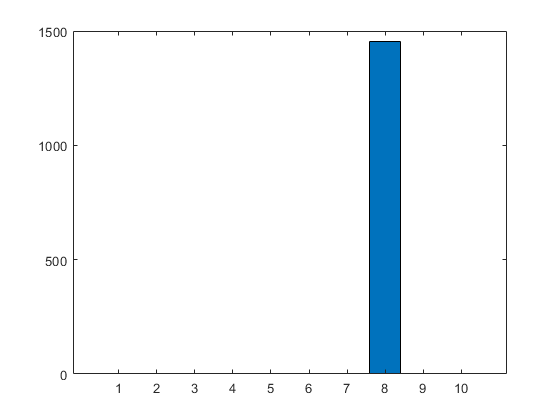




%player 8 filter

x8 = square(2*pi*players(8)*t);


F81 = filter(b1, a1, x8);
F82 = filter(b2, a2, x8);
F83 = filter(b3, a3, x8);
F84 = filter(b4, a4, x8);
F85 = filter(b5, a5, x8);
F86 = filter(b6, a6, x8);
F87 = filter(b7, a7, x8);
F88 = filter(b8, a8, x8);
F89 = filter(b9, a9, x8);
F810 = filter(b10, a10, x8);

Fe8 = 1:10;

Fe8(1) = sum(F81 .^2);
Fe8(2) = sum(F82 .^2);
Fe8(3) = sum(F83 .^2);
Fe8(4) = sum(F84 .^2);
Fe8(5) = sum(F85 .^2);
Fe8(6) = sum(F86 .^2);
Fe8(7) = sum(F87 .^2);
Fe8(8) = sum(F88 .^2);
Fe8(9) = sum(F89 .^2);
Fe8(10) = sum(F810 .^2);

figure(10);

bar(Fe8);

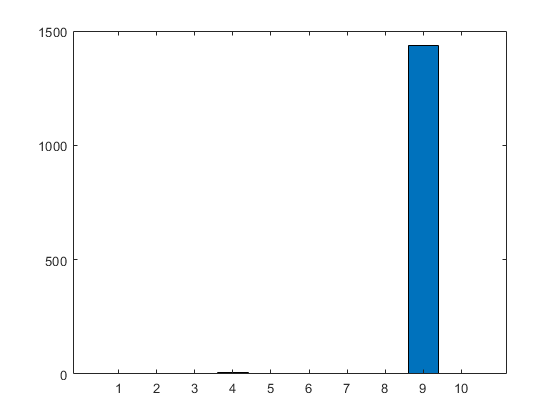


%player 9 filter

x9 = square(2*pi*players(9)*t);


F91 = filter(b1, a1, x9);
F92 = filter(b2, a2, x9);
F93 = filter(b3, a3, x9);
F94 = filter(b4, a4, x9);
F95 = filter(b5, a5, x9);
F96 = filter(b6, a6, x9);
F97 = filter(b7, a7, x9);
F98 = filter(b8, a8, x9);
F99 = filter(b9, a9, x9);
F910 = filter(b10, a10, x9);

Fe9 = 1:10;

Fe9(1) = sum(F91 .^2);
Fe9(2) = sum(F92 .^2);
Fe9(3) = sum(F93 .^2);
Fe9(4) = sum(F94 .^2);
Fe9(5) = sum(F95 .^2);
Fe9(6) = sum(F96 .^2);
Fe9(7) = sum(F97 .^2);
Fe9(8) = sum(F98 .^2);
Fe9(9) = sum(F99 .^2);
Fe9(10) = sum(F910 .^2);

figure(11);

bar(Fe9);

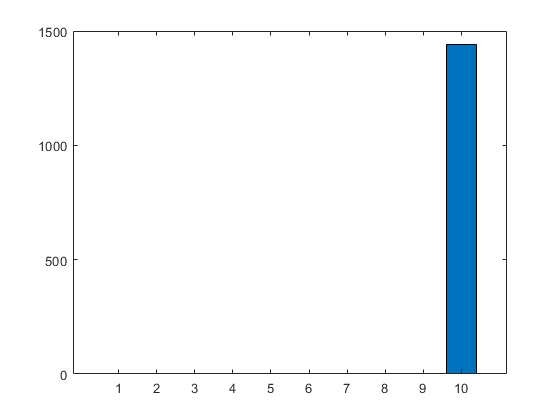



%player 10 filter

x10 = square(2*pi*players(10)*t);


F101 = filter(b1, a1, x10);
F102 = filter(b2, a2, x10);
F103 = filter(b3, a3, x10);
F104 = filter(b4, a4, x10);
F105 = filter(b5, a5, x10);
F106 = filter(b6, a6, x10);
F107 = filter(b7, a7, x10);
F108 = filter(b8, a8, x10);
F109 = filter(b9, a9, x10);
F1010 = filter(b10, a10, x10);

Fe10 = 1:10;

Fe10(1) = sum(F101 .^2);
Fe10(2) = sum(F102 .^2);
Fe10(3) = sum(F103 .^2);
Fe10(4) = sum(F104 .^2);
Fe10(5) = sum(F105 .^2);
Fe10(6) = sum(F106 .^2);
Fe10(7) = sum(F107 .^2);
Fe10(8) = sum(F108 .^2);
Fe10(9) = sum(F109 .^2);
Fe10(10) = sum(F1010 .^2);

figure(12);

bar(Fe10);